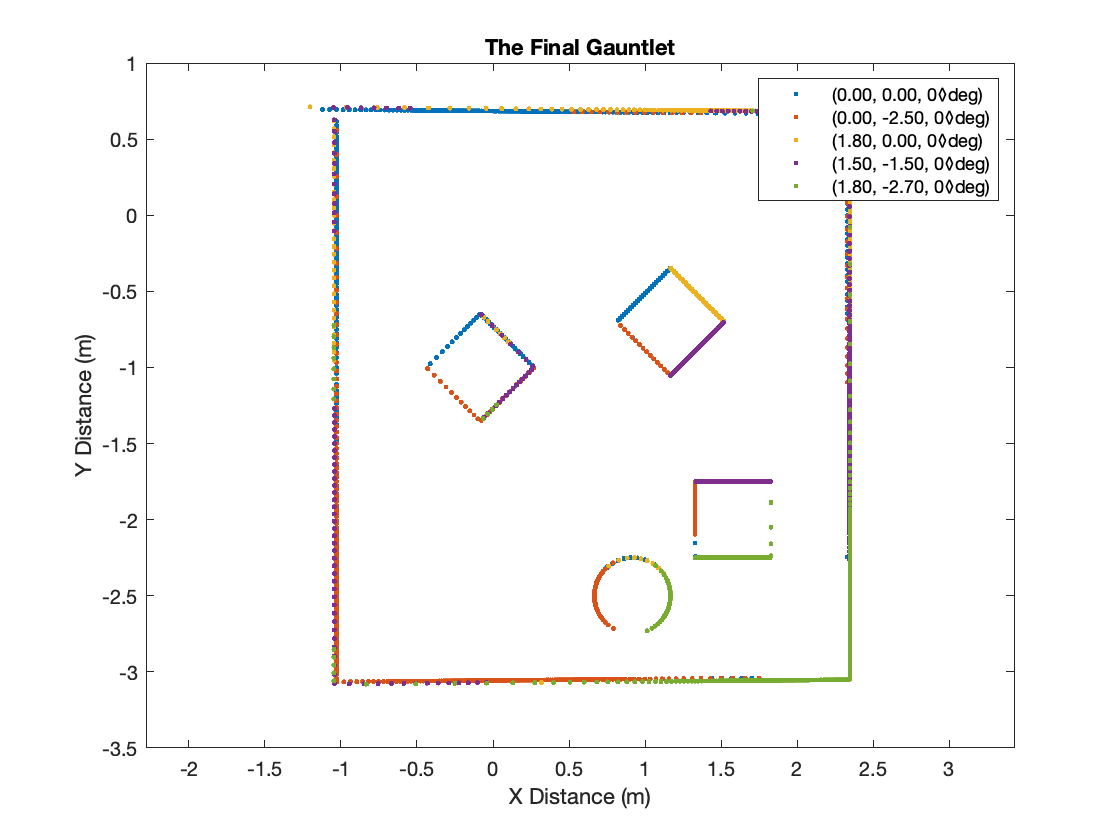

load('scans/lidar2.mat', 'lidar_results', 'lidar_positions');
% lidar.mat has a lidar matrix which is n x 2 x m, where each (:, :, m) is
% one scan in the form of [r, theta], where r and theta are column vectors.
% It also has a 3 x m matrix of column vectors of the format [x, y, phi]

clf;

for i=1:size(lidar_results, 3)
    r_G = to_global(lidar_results(:, 1, i), lidar_results(:, 2, i), lidar_positions(i, 1:2), lidar_positions(i, 3));
    
    label = sprintf("(%1.2f, %1.2f, %1.0f◊deg)", lidar_positions(i, 1), lidar_positions(i, 2), lidar_positions(i, 3));
        
    plot(r_G(:, 1), r_G(:, 2), '.', 'DisplayName', label); hold on;
end

legend show;
title("The Final Gauntlet");
xlabel("X Distance (m)");
ylabel("Y Distance (m)");
xlim([-1.5, 3]);
ylim([-3.5, 1]);

axis equal;

hold off;

function r_G = to_global(R, theta, origin, phi)
    [X_raw, Y_raw] = pol2cart(theta, R);
    r_L = [X_raw, Y_raw, ones(length(X_raw), 1)]';
    r_N = [1, 0, 0.084; 0, 1, 0; 0, 0, 1] * r_L; % no rotation needed
    r_G_raw = [1, 0, origin(1); 0, 1, origin(2); 0, 0, 1] * [cos(phi), -sin(phi), 0; sin(phi), cos(phi), 0; 0, 0, 1] * r_N;
    r_G = r_G_raw(1:2, :)';
end

function r_G = plot_helper(position, results, desc)
    if nargin < 3
        desc = "Neato's View";
    end
    
    % old params: R, theta, origin, phi, desc


end